# 二维绘图进阶

1、errorbar 含误差条的线图

2、histogram 直方图

3、scatter 散点图

4、bar 柱状图

5、pie 饼图

## 误差图

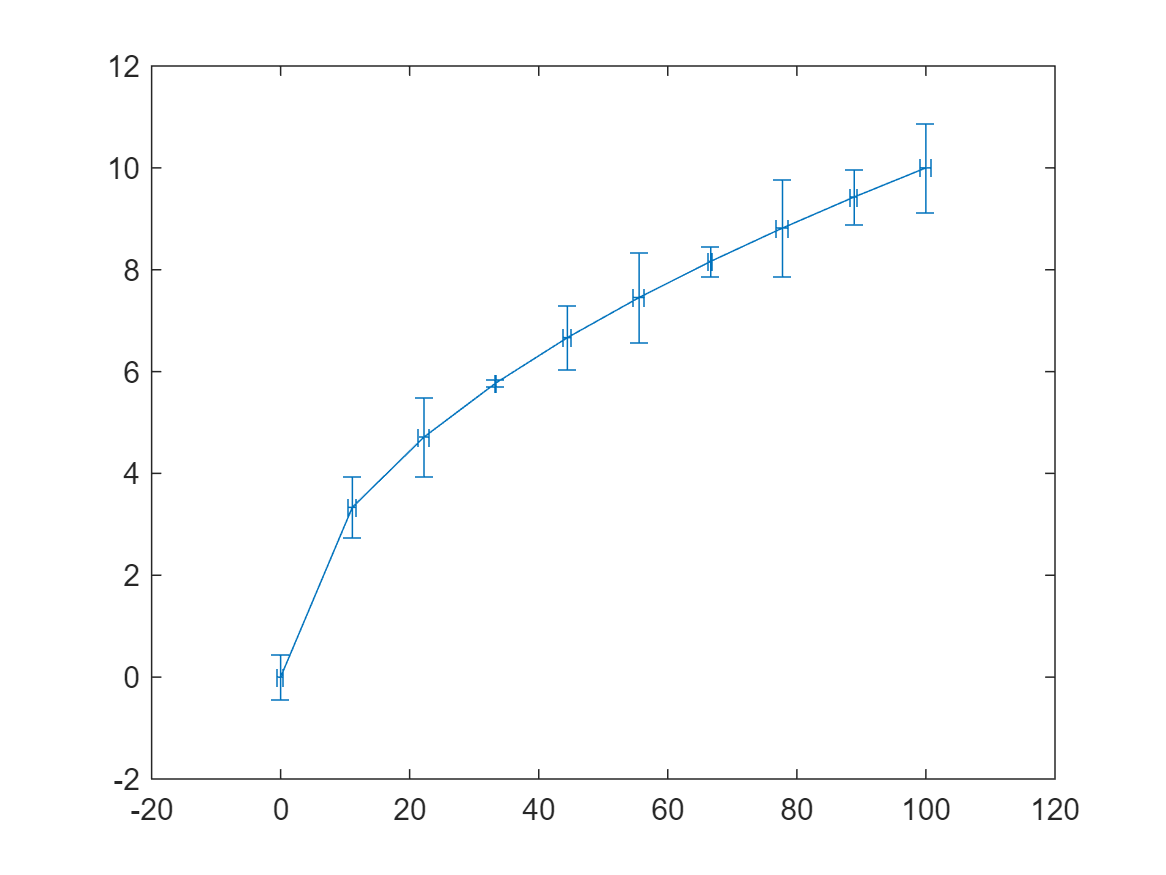

% errorbar(x, y, err)

x = linspace(0, 100, 10);
y = x.^0.5;
err = rand(size(x));

errorbar(x, y, err, 'both');

## 直方图

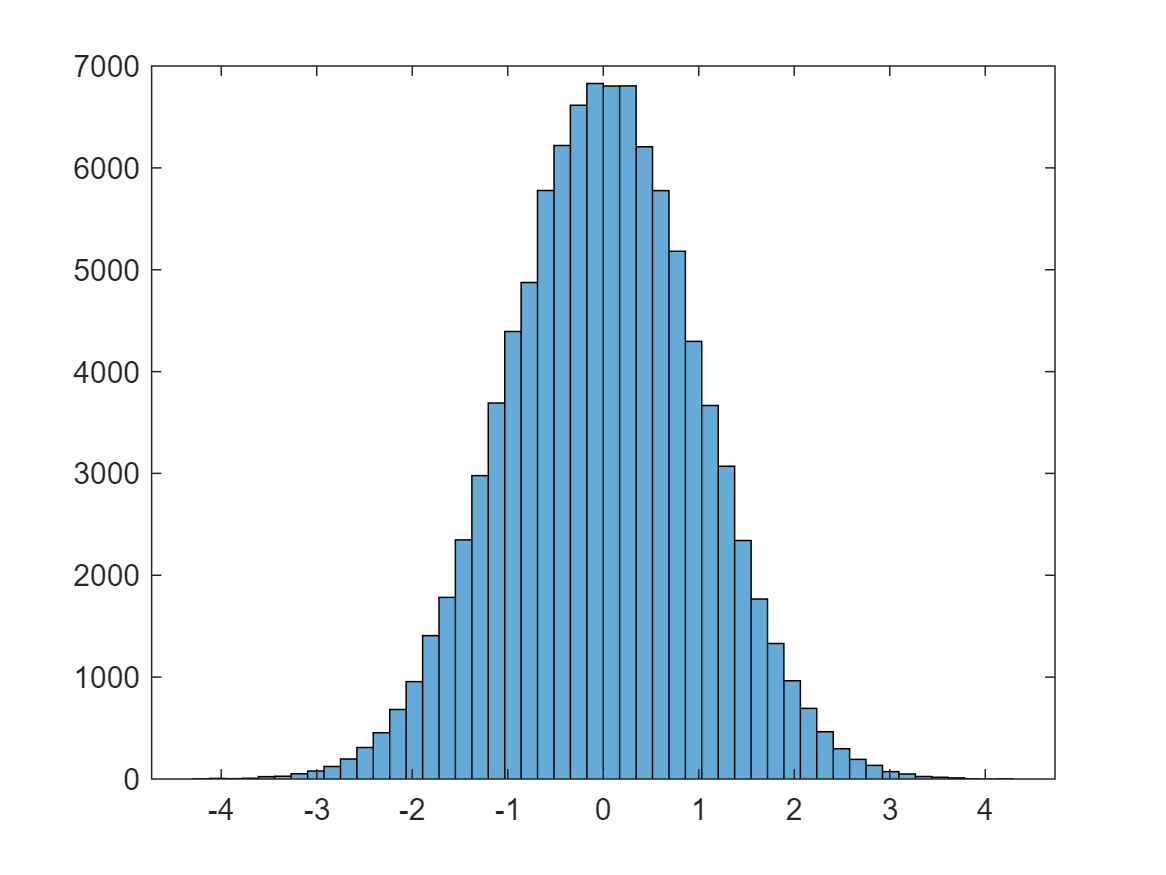

% histogram(x, n)  %基于x创建直方图，n为区间数量

    x = randn([1, 100000]);
n = 50;
histogram(x, n);

## 散点图

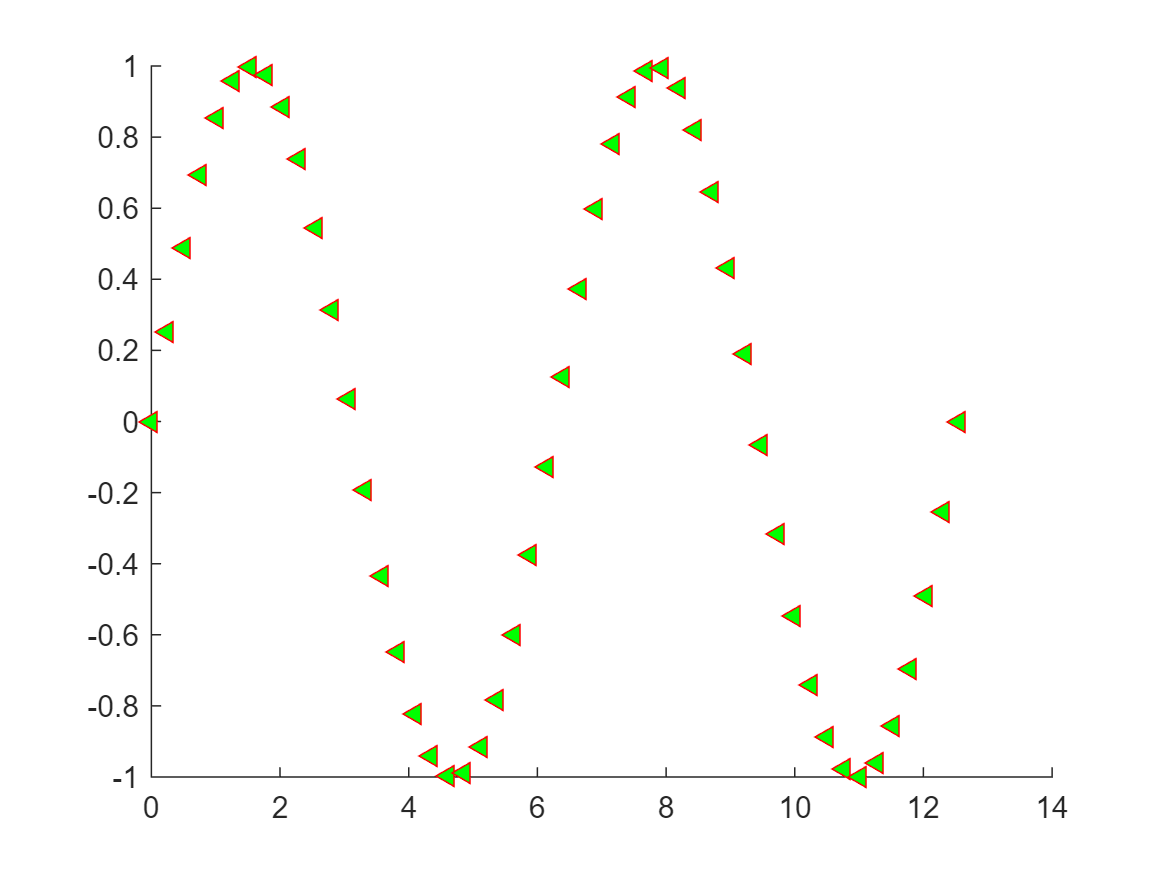

% scatter(x, y)     %在向量x和y指定的位置创建一个包含圆形的散点图

x = linspace(0, 4*pi, 50);
y = sin(x);

scatter(x, y, '<', "filled", 'g', "MarkerEdgeColor", 'r');

## 柱状图

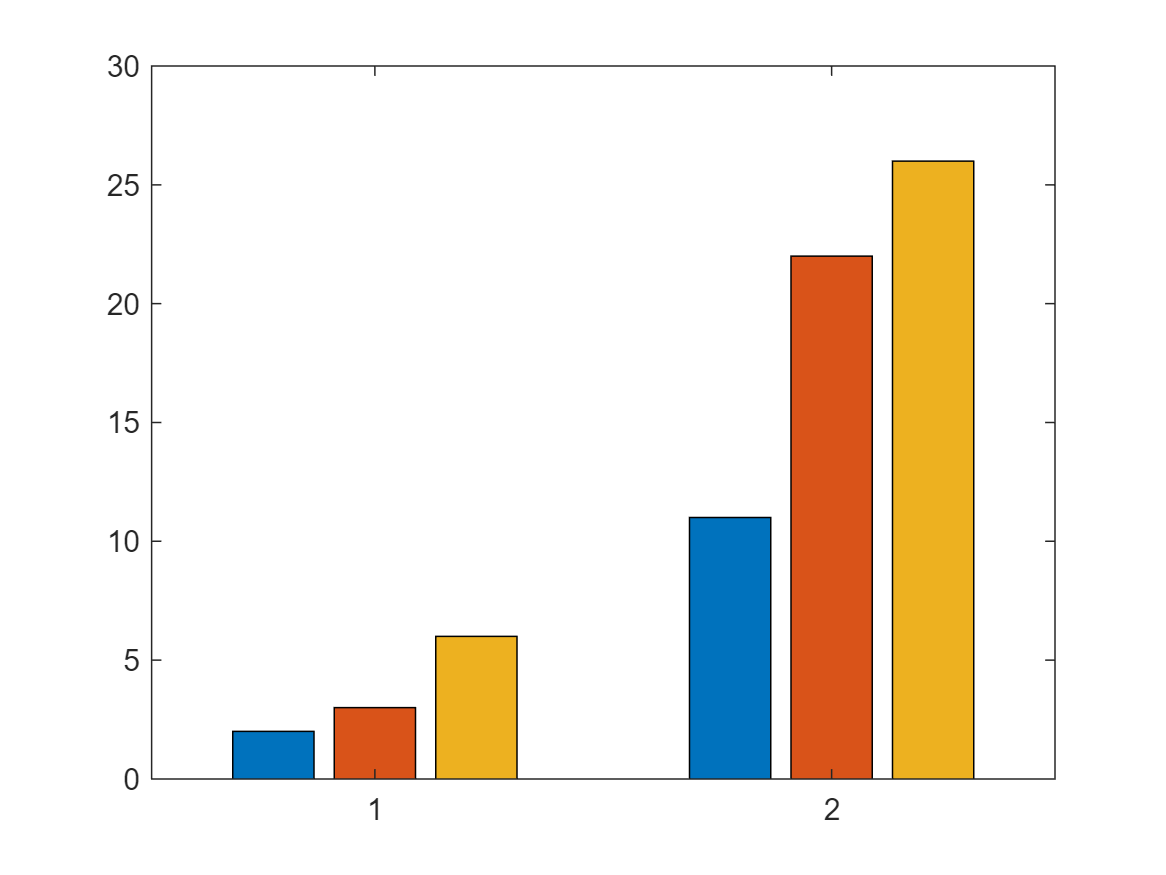

% bar(y)   %创建一个条形图，y中的每一个元素对应一个条形
           %如果y是m×n矩阵，则bar创建每组包含n个条形图的m个组


y = [2 3 6; 11 22 26];
bar(y);

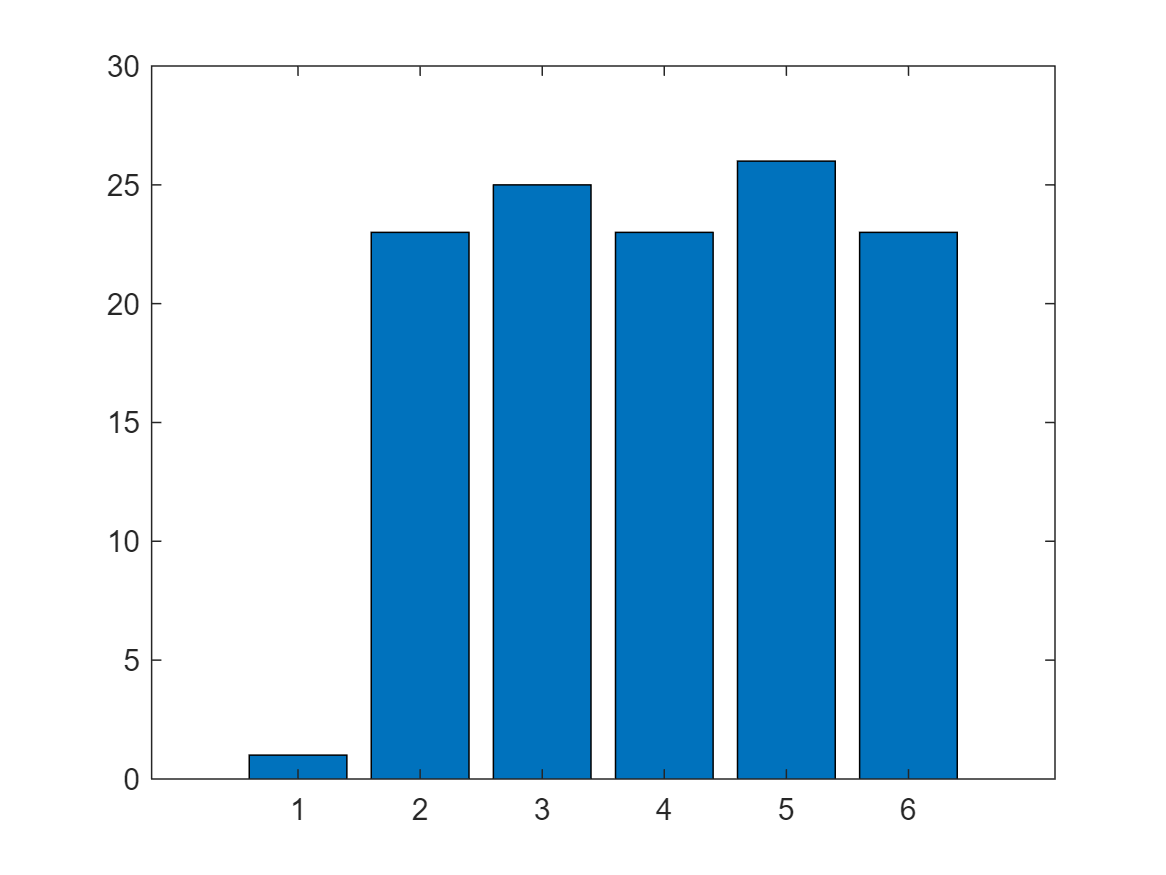

y2 = [1 23 25 23 26 23];
bar(y2);

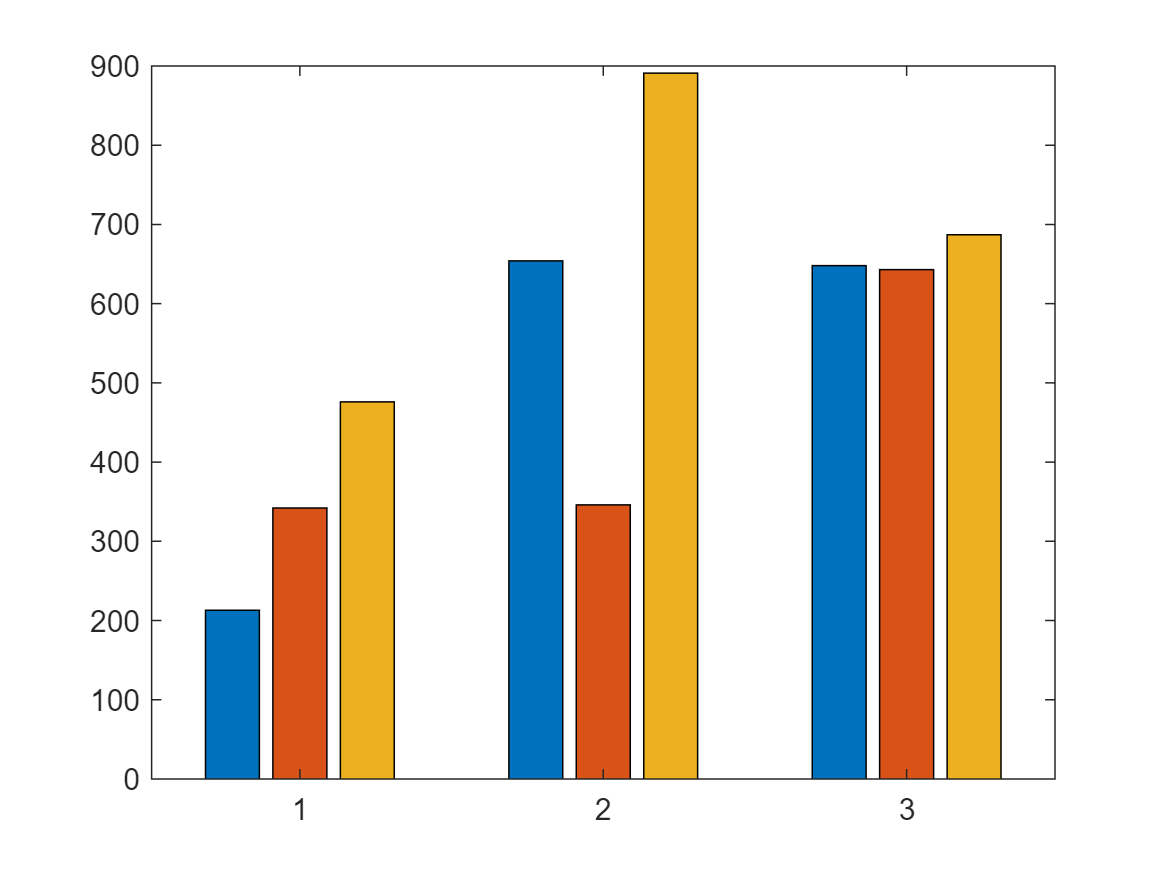

y3 = [213 342 476; 654 346 891; 648 643 687];
bar(y3);

## 饼状图

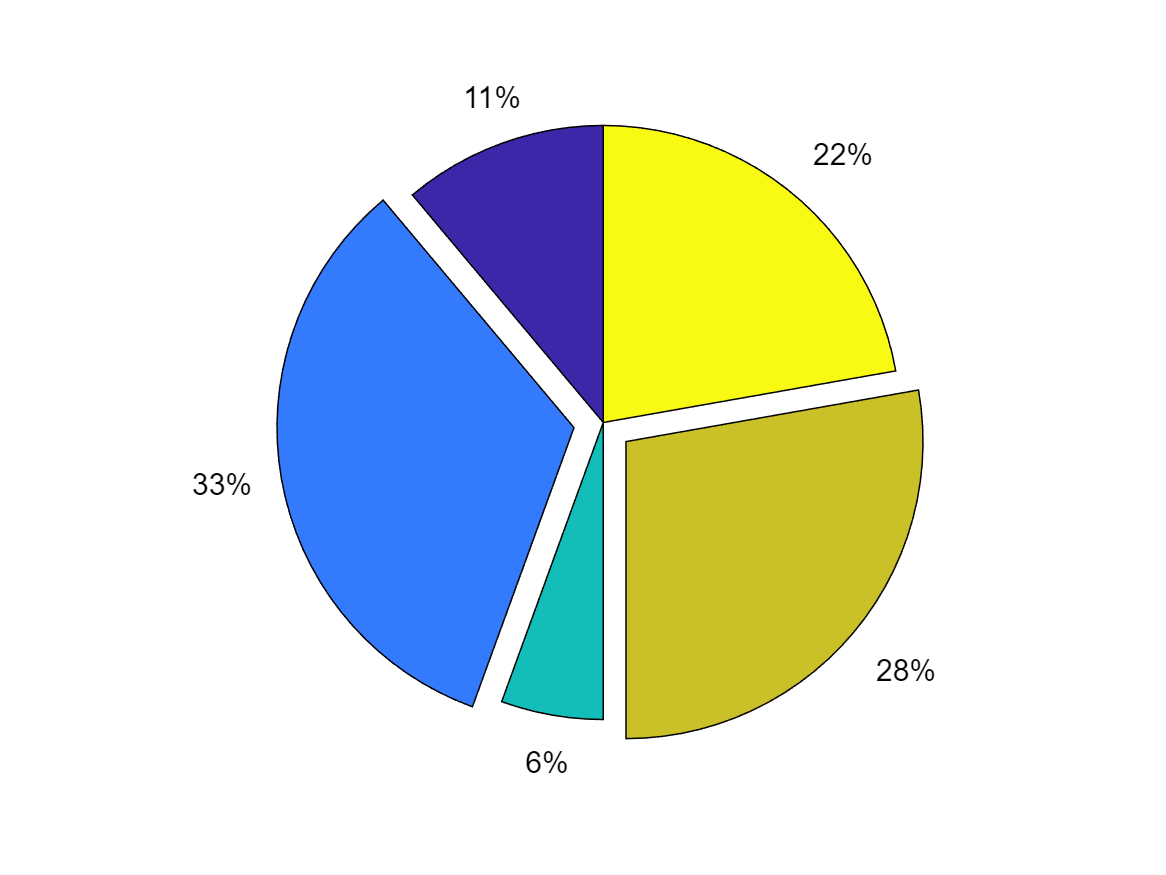

% pie(X, explode)  %使用X中的数据绘制饼状图，饼状的每个扇区代表X中的一个元素；
                   %explode将扇区从饼状图偏移一定位置

X =[ 1 3 0.5 2.5 2];
explode = [0 1 0 1 0];
pie(X, explode);